## Instructions

Write a function that loads attached data and firs a SVM model to it.

You must hit at least **99.0%** accuracy on the data

## Data

4000+ datapoints, 36 column features and their corresponding labels (column 37). Label 1 means the asteroid classified as hazardous, 0 - non-hazardous. Descriptions for each column can be found below. For this exercise the data has been simplified to include only features varying between asteroids.

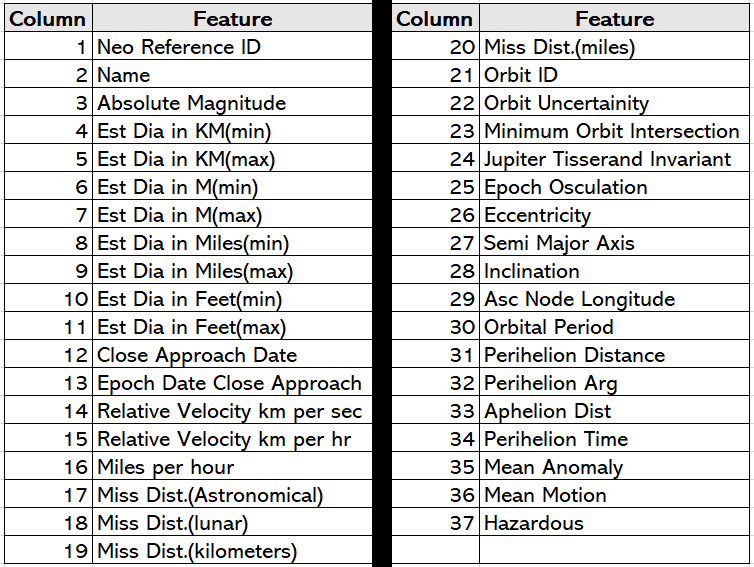

Detailed explanation of this function.

clear
clc

load('svm_nasa_data_train.mat')
% load('svm_nasa_data_test.mat')
model = mysvm(data);

   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356
   -0.4356
    2.2951
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
    2.2951
    2.2951
    2.2951
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356
   -0.4356
    2.2951
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
   -0.4356
    2.2951
   -0.4356

accuracy = 1

precision = 1

recall = 1

F1score = 1


% % Returns labels and probabilities of prediction
% [label,~] = predict(model,Ptest(:,1:36))
% accuracy = 1 - sum(abs(label - Ptest(:,37)))/length(label)

function [model] = mysvm(data)
    %%%%%%% BEGIN SOLUTION %%%%%%%
    % Feature scaling
    mu = mean(data,1);
    sigma = std(data,0,1);
    data2 = data;
    for i = 1:37
        data2(:,i) = (data(:,i)-mu(i)) / sigma(i);
    end

    % Reserve 20% of data for testing 
    cv = cvpartition(size(data2,1),'HoldOut',0.2);
    % Training data
    X = data2(cv.training,1:36); 
    Y = data2(cv.training,37);
    % Test data
    X_test = data2(cv.test,1:36);
    y_test = data2(cv.test,37);

    % Visualise data
    coeff = pca(X);
    
    % Model
    model = fitcsvm(X,Y,...
        'KernelFunction','gaussian',...
        'KernelScale','auto',...
        'Standardize',true, ...
        'BoxConstraint',10,...
        'Verbose', 0);

    % Return labels and probabilities of prediction
    [label,~] = predict(model,X_test); 

    % Metrics for classification
    TP = sum(and(label,y_test));                % True positives
    FP = sum(and(label,not(y_test)));           % False positives
    TN = sum(and(not(label),not(y_test)));      % True negatives
    FN = sum(and(not(label),y_test));           % False negatives
    
    accuracy  = (TP + TN)/(TP + TN + FP + FN)
    precision = TP/(TP + FP)
    recall    = TP/(TP + FN)
    F1score   = (2*precision*recall)/(precision + recall)
    %%%%%%% END SOLUTION %%%%%%%%%
    end
